% [audio, Fs] = audioread('song.mp3');
% mfccs = mfcc(audio, Fs);
% imagesc(mfccs);
% colormap('jet');
% colorbar;
% title('MFCC Heatmap of the Song');
% xlabel('Time');
% ylabel('MFCC Coefficients');

% detectedChords = Chordination('song.mp3', 0, 0);
% [uniqueChords, ~, ic] = unique(detectedChords);
% chordCounts = accumarray(ic, 1);
% bar(chordCounts);
% set(gca, 'xticklabel', uniqueChords);
% title('Chord Frequency in the Song');
% xlabel('Chord');
% ylabel('Frequency');

% coeff = pca(features');
% scatter(coeff(:,1), coeff(:,2));
% title('PCA Scatter Plot of Songs');
% xlabel('Principal Component 1');
% ylabel('Principal Component 2');

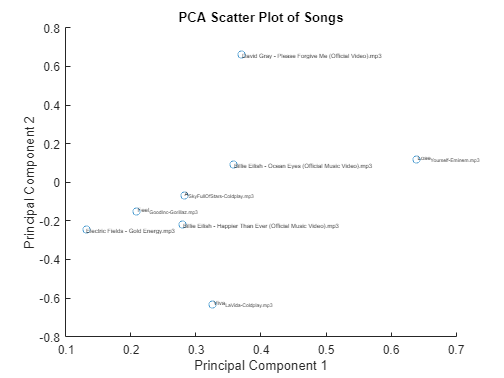

% Assuming coeff is the result of PCA on your features
coeff = pca(features');
scatter(coeff(:,1), coeff(:,2));
title('PCA Scatter Plot of Songs');
xlabel('Principal Component 1');
ylabel('Principal Component 2');

% Annotate each point with its corresponding filename
for i = 1:length(filenames)
    text(coeff(i,1), coeff(i,2), filenames{i}, 'FontSize', 5);
end

% bpms = arrayfun(@(x) BPM(audioread(x), Fs), filenames);
% histogram(bpms);
% title('BPM Distribution of Songs');
% xlabel('BPM');
% ylabel('Number of Songs');

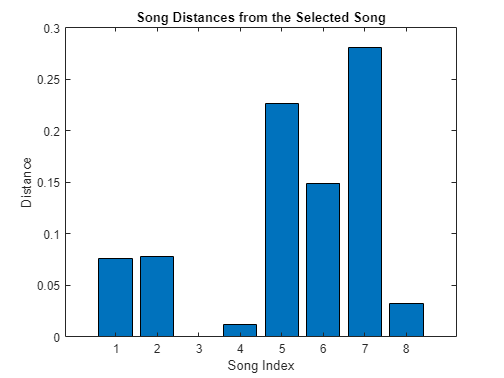

bar(songDistances);
title('Song Distances from the Selected Song');
xlabel('Song Index');
ylabel('Distance');

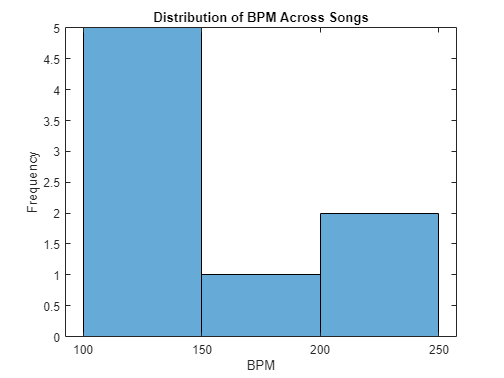

histogram(features(:,1)); % Assuming the first column is BPM
title('Distribution of BPM Across Songs');
xlabel('BPM');
ylabel('Frequency');

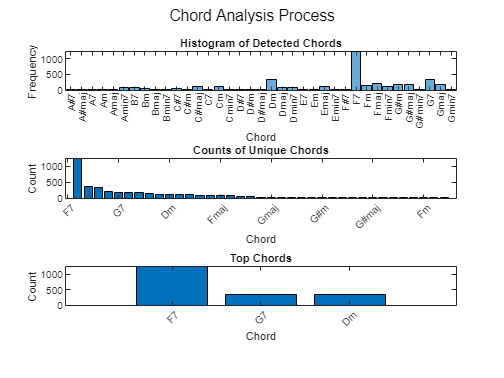

% detectedChords is obtained from Chordination
detectedChords = Chordination("./../Songs/" + cell2mat(filenames(2)), 0, 0, 0.25, 10, 'simple');

% Count and sort the chords
[uniqueChords, ~, ic] = unique(detectedChords);
chordCounts = accumarray(ic, 1);
[sortedCounts, idx] = sort(chordCounts, 'descend');
topChords = uniqueChords(idx(1:min(3, length(idx)))); 

% Plotting the process
figure;

% Subplot 1: Histogram of detected chords
subplot(3,1,1);
histogram(categorical(detectedChords));
title('Histogram of Detected Chords');
xlabel('Chord');
ylabel('Frequency');

% Subplot 2: Bar chart of unique chords and their counts
subplot(3,1,2);
bar(chordCounts(idx));
set(gca, 'xticklabel', uniqueChords(idx), 'XTickLabelRotation', 45);
title('Counts of Unique Chords');
xlabel('Chord');
ylabel('Count');

% Subplot 3: Top chords
subplot(3,1,3);
bar(sortedCounts(1:min(3, length(sortedCounts))));
set(gca, 'xticklabel', topChords, 'XTickLabelRotation', 45);
title('Top Chords');
xlabel('Chord');
ylabel('Count');

% Adjust layout
sgtitle('Chord Analysis Process');